Model problem to test the leapfrogging method for the wave equation on the dumbbell graph subject to Kirchhoff vertex conditions.

The program solves

 
$$u_{tt} = \triangle  u  -\sin{u}+ f(x,t)\\
u(0) = \psi_1(x) \\
\partial_t u(0) = \psi_2(x)$$


on the dumbbell graph with $L=2\pi$ on all edges. The forcing function $f(x,t)$ is constructed as follows:

Let $u(x,t) = \sech{t}\cdot \psi_1(x) + \tanh{t}\cdot \psi_2(x)$ where $\psi_1$ and $\psi_2$ are eigenfunctions of the Laplacian with simple eigenvalues $\lambda_1$ and $\lambda_2$. Then let $f(x,t) = u_{tt} - \triangle u $. By construction, the function $u(x,t)$ now solves the given PDE and satisfies the vertex conditions.

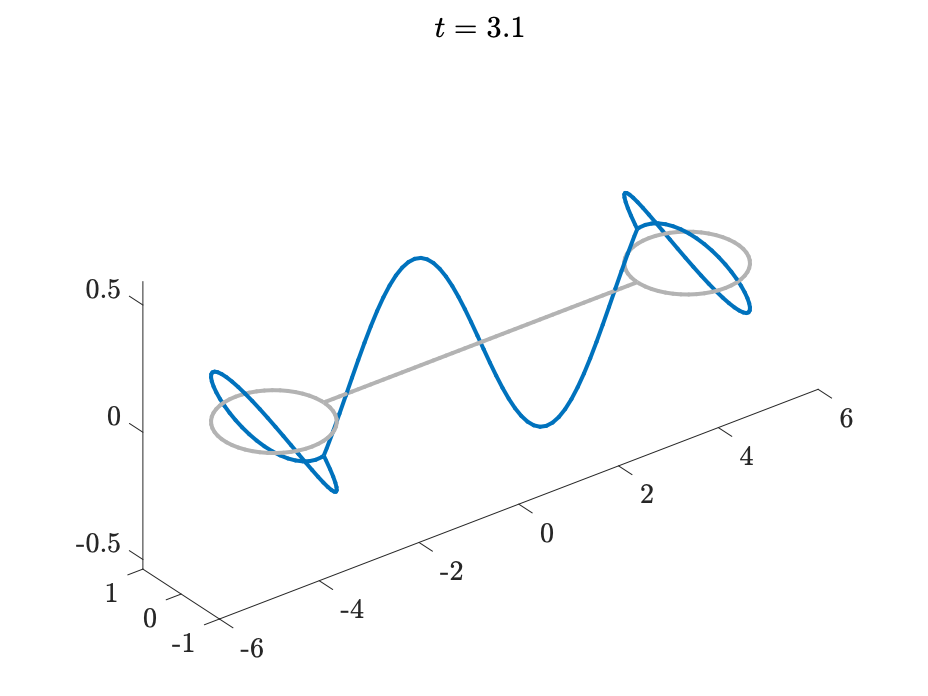

The maximum error with 50 points/unit length is 2.020e-04.


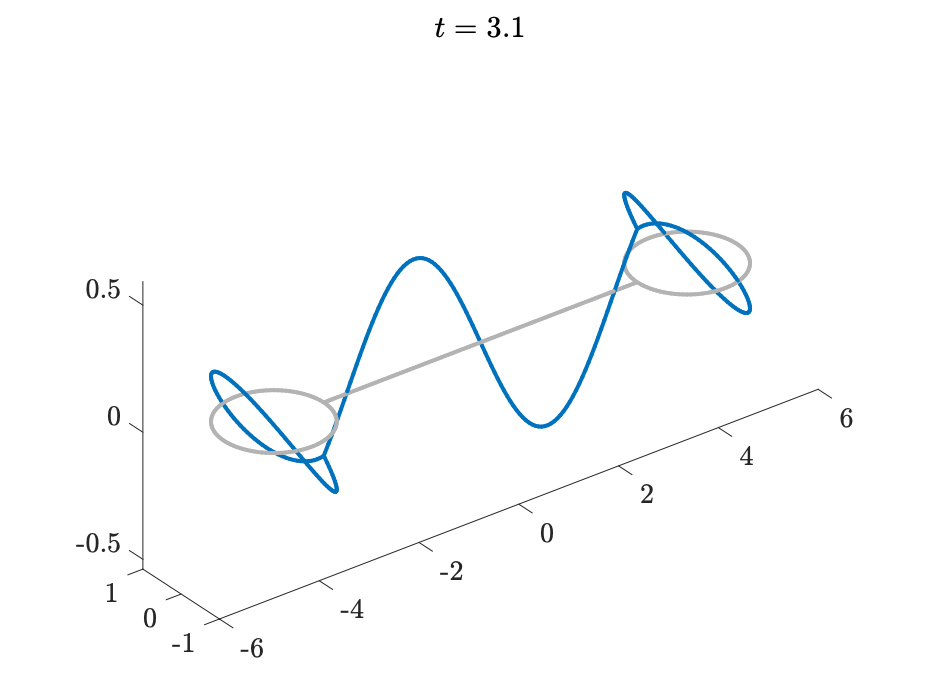

The maximum error with 100 points/unit length is 5.047e-05.


clear

tfinal = 2*pi;
nx=50;
errorvec=zeros(1,2);
for j = 1:2
    source=[1 1 2]; target=[1 2 2]; L = [2*pi,2*pi, 2*pi];
    Phi = quantumGraph(source,target,L,'nx',nx/2/pi);
    Phi.addPlotCoords(@dumbbellPlotCoords);
    nt = nx;
    h = tfinal/nt;
    L0 = Phi.laplacianMatrixWithZeros;
    P0 = Phi.interpolationMatrixWithZeros;
    PVC = Phi.interpolationMatrixWithVC;

    [V,lambda]=Phi.eigs(12);
    psi1 = V(:,4);  
    psi2 = V(:,8);  
    lambda1 = lambda(4); % This eigenvalue is about -0.646
    lambda2 = lambda(8); % This eigenvalue is about -1.428

    uExact = @(t) sech(t)*psi1 + tanh(t)*psi2;
    f = @(t) sech(t)*(1-lambda1-2*sech(t)^2)*psi1 + tanh(t)*(-2*sech(t)^2 -lambda2)*psi2+sin(uExact(t));

    u0 = uExact(0);
    v0 = psi2;
    % The approximate solution at t=h, correct to O(h^2) and satisfying the
    % vertex conditions
    u1 = PVC\(P0*(u0+h*(v0+(f(0)-sin(u0))*h/2))+(h^2/2)*(L0*u0));
    U = [u0 u1];
    t = h;
    for k=2:nt
        uNew = PVC\ (P0*(u1 + (u1-u0)+ h^2*(f(t)-sin(u1)) ) + h^2*(L0*u1));
        u0 = u1;
        u1 = uNew;
        U = [U uNew];
        t = t+h;
    end
    t = linspace(0,tfinal,nt+1);
    figure;
    Phi.animatePDESolution(U,t,j);

    errorvec(j)=max(abs((u1-uExact(tfinal))));
    fprintf('The maximum error with %i points/unit length is %0.3d.\n',nx,errorvec(j))
    nx = 2*nx;
end

order = log2(errorvec(1)/errorvec(2));
fprintf('The approximate order of convergence is %0.3g.\n',order)

The approximate order of convergence is 2.
